%----------------- GROUP 07 -----------------
% Authors: Simone Guidolin, Nicola Cigarini, 
% Gioel Adriano Vencato
% Project: P03 UGV on-road management 

clc;
clear;
close all;

% Load all required parameters
run('parameters.m');

# Tracking --> Reference expressed in v,w

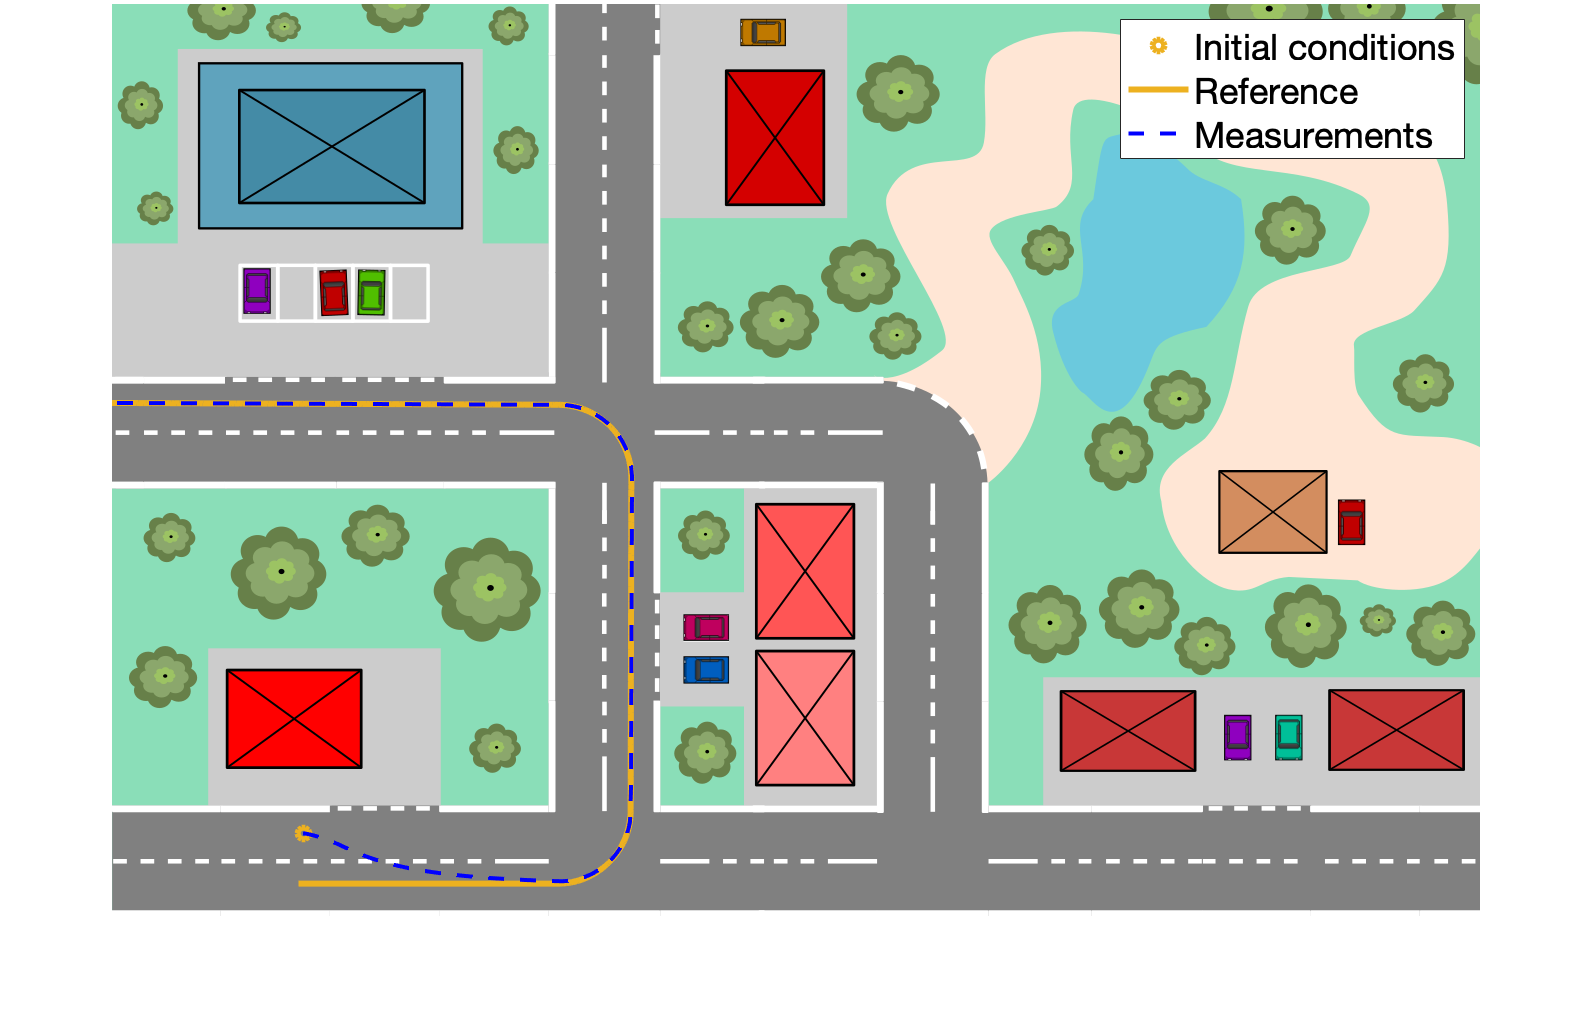

%
% Unicycle
%
% Initial conditions
% unicycle.ic.theta = -pi/2;
% unicycle.ic.x = 3.2;
% unicycle.ic.y = 2.;
unicycle.ic.theta = 0;
unicycle.ic.x = 2.10;
unicycle.ic.y = 0.9;

%
% Tracking reference signal
%
% Set initial conditions
% tracking.x0 = unicycle.ic.x;
% tracking.y0 = unicycle.ic.y;
% tracking.theta0 = unicycle.ic.theta;
tracking.x0 = 2.05;
tracking.y0 = 0.35;
tracking.theta0 = 0;

% Steering points
% tracking.points = [tracking.x0, tracking.y0; 3.2, 0.85; 3.70, 0.35; 4.9, 0.35; 
%                5.7, 1.15; 5.7, 4.8; 4.9, 5.6; 2.8, 5.6; -1, 5.6];
tracking.points = [tracking.x0, tracking.y0; 3.70, 0.35; 4.9, 0.35; 
               5.7, 1.15; 5.7, 4.8; 4.9, 5.6; 2.8, 5.6; -1, 5.6];

% Kind of reference --> 0: horizontal/vertical/curvilinear stretches
%                   --> 1: smooth lines
% Compute the reference signals for the first subpath: v, w
tracking.kind_reference = 0;
[tracking.x, tracking.y, tracking.theta, tracking.v, tracking.w] = generate_reference(tracking.points(:,1), tracking.points(:,2), ...
                                tracking.x0, tracking.y0, tracking.theta0, unicycle.diffDrive.Td, tracking.kind_reference);

% Define reference signals as timeseries
tracking.time = 0 : unicycle.diffDrive.Td : (length(tracking.v) - 1) * unicycle.diffDrive.Td;
tracking.v_ts = timeseries(tracking.v, tracking.time);
tracking.w_ts = timeseries(tracking.w, tracking.time);

%
% Obstacle
%
obstacle.p = [0; 0];

%
% Parking place
%
park.x = tracking.x(end) - 0.1;
park.y = tracking.y(end);
park.theta = tracking.theta(end);

%
% Simulation
%
simulation.stop_time = 29;
simulation.starting_controller = 1;
set_param('simulation_scheme_vel/Reference generator/Tracking/NonHolonomic/Integrator1','InitialCondition','tracking.theta0');
set_param('simulation_scheme_vel/Reference generator/Tracking/NonHolonomic/Integrator2','InitialCondition','[tracking.x0 tracking.y0]');
set_param('simulation_scheme_vel/Reference generator/Tracking/final_p_ref','Value','tracking.points(end,:)');
set_param('simulation_scheme_vel/Reference generator/Tracking/final_theta_ref','Value','tracking.theta(end)');
out = sim('simulation_scheme_vel.slx');

%
% Results
%
figure(1);
imshow(map.img.data); % image
hold on;
plot(x_view(unicycle.ic.x, map.x_max, map.img.width), ...
    y_view(unicycle.ic.y, map.y_max, map.img.height), ...
    'o', 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250]); % Initial conditions
plot(x_view(tracking.x, map.x_max, map.img.width), ...
    y_view(tracking.y, map.y_max, map.img.height), ...
    'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250]); % Tracking reference signal
plot(x_view(out.p.Data(:,1), map.x_max, map.img.width), ...
    y_view(out.p.Data(:,2), map.y_max, map.img.height), ...
    'LineWidth', 2, 'LineStyle', '--', 'Color', 'blue'); % Measurements
lgd = legend('Initial conditions', 'Reference', 'Measurements'); 
lgd.FontSize = 18;
hold off

## Unicycle state

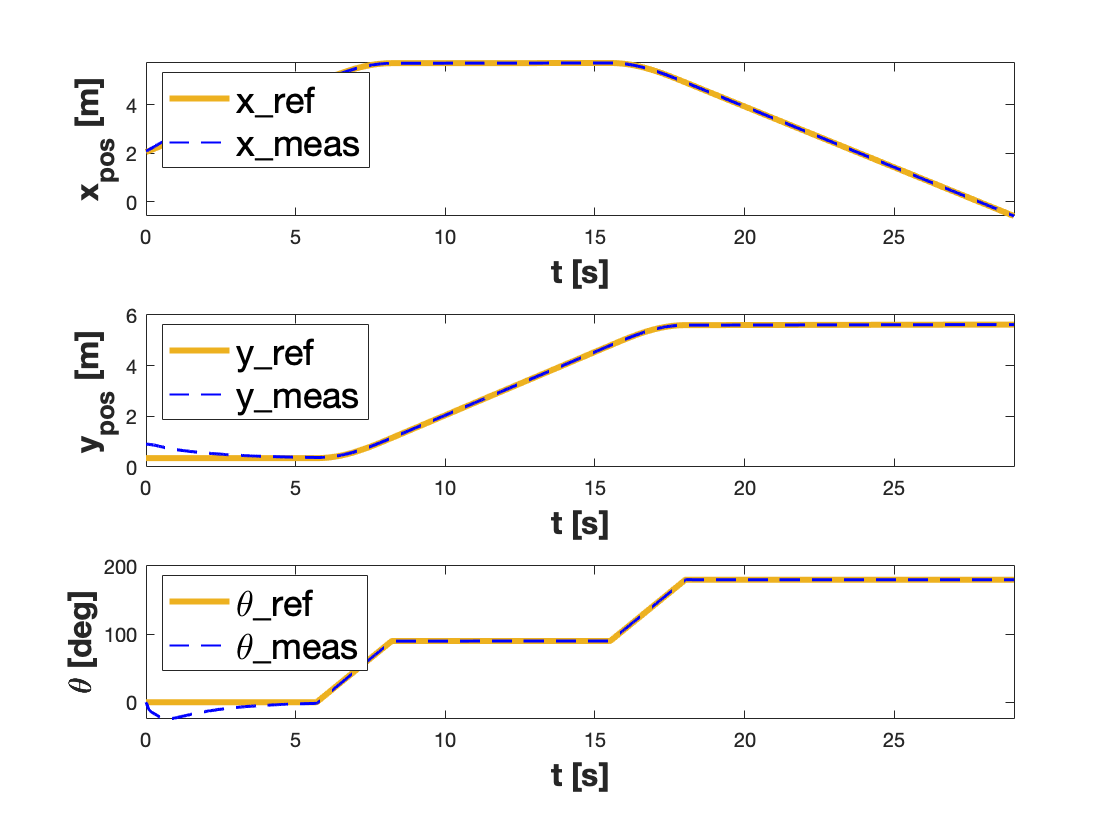

figure(2);
subplot(3,1,1);
plot(out.p_ref.Time, out.p_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.p.Time, out.p.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("x_{pos} [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["x\_ref" "x\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
xlim([0 simulation.stop_time])
hold off

subplot(3,1,2);
plot(out.p_ref.Time, out.p_ref.Data(:,2), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.p.Time, out.p.Data(:,2),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("y_{pos} [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["y\_ref" "y\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
xlim([0 simulation.stop_time])
hold off

subplot(3,1,3);
plot(out.theta_ref.Time, out.theta_ref.Data(:,1) .* rad2deg, 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.theta.Time, out.theta.Data(:,1).* rad2deg,'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\theta [deg]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\theta\_ref" "\theta\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
xlim([0 simulation.stop_time])
hold off

## State errors

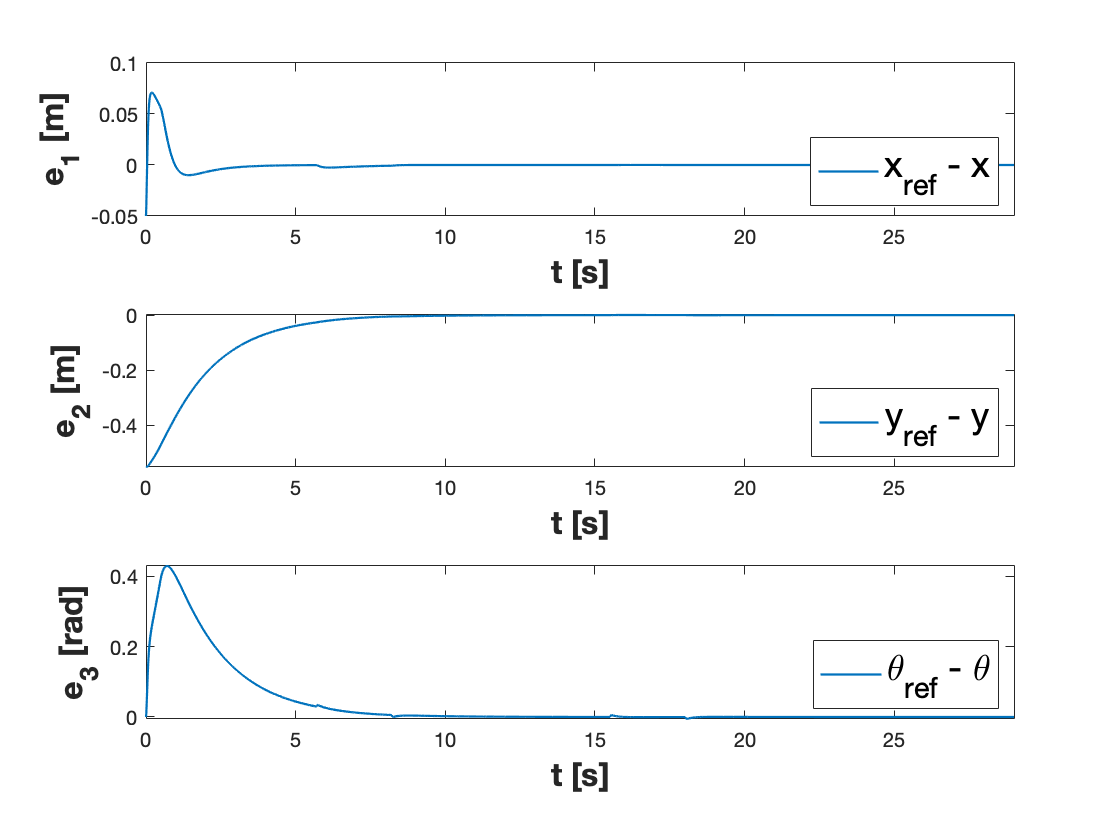

figure(3);
subplot(3,1,1);
plot(out.e1.Time, out.e1.Data(:,1), 'LineWidth', 1.1)
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("e_1 [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["x_{ref} - x"], 'Location', 'southeast');
lgd.FontSize = 18;
xlim([0 simulation.stop_time])
hold off

subplot(3,1,2);
plot(out.e2.Time, out.e2.Data(:,1), 'LineWidth', 1.1)
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("e_2 [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["y_{ref} - y"], 'Location', 'southeast');
lgd.FontSize = 18;
xlim([0 simulation.stop_time])
hold off

subplot(3,1,3);
plot(out.e3.Time, out.e3.Data(:,1), 'LineWidth', 1.1)
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("e_3 [rad]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\theta_{ref} - \theta"], 'Location', 'southeast');
lgd.FontSize = 18;
xlim([0 simulation.stop_time])
hold off

## Control effort

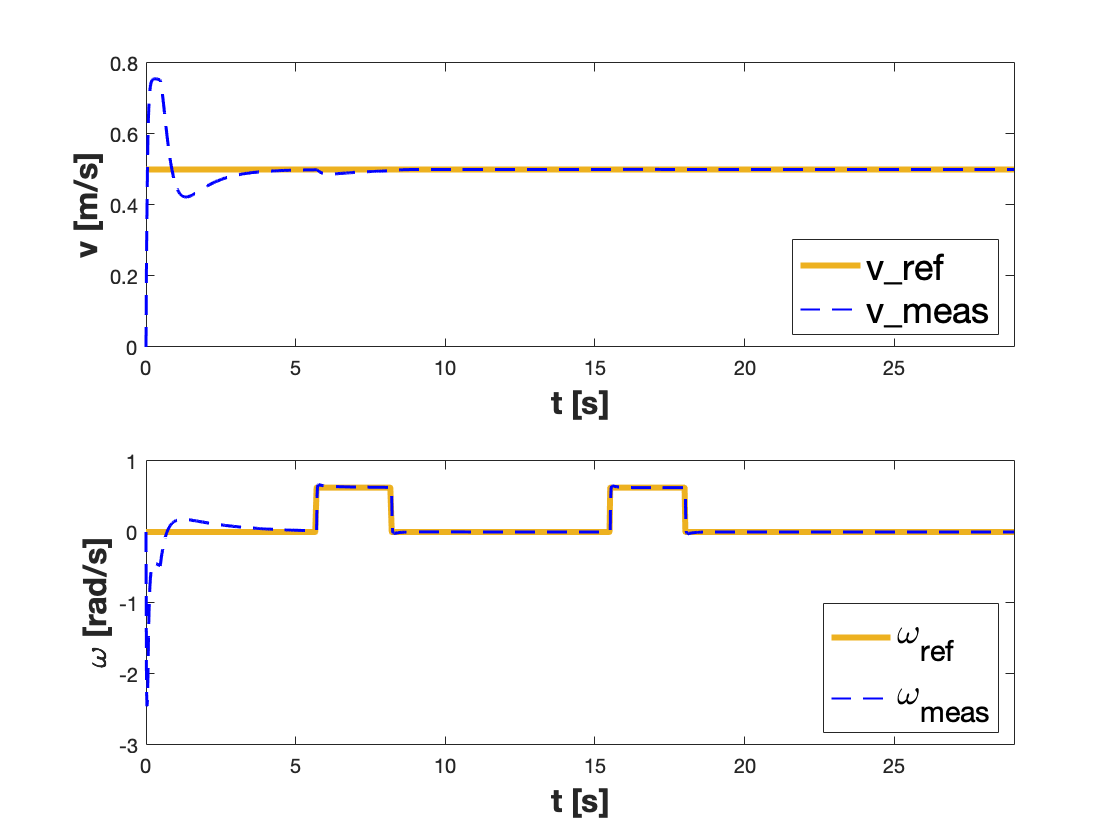

figure(4);
subplot(2,1,1)
plot(out.v_ref.Time, out.v_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.v.Time, out.v.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("v [m/s]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["v\_ref" "v\_meas"], 'Location', 'southeast');
lgd.FontSize = 18;
xlim([0 simulation.stop_time])
hold off

subplot(2,1,2)
plot(out.w_ref.Time, out.w_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.w.Time, out.w.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\omega [rad/s]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\omega_{ref}" "\omega_{meas}"], 'Location', 'southeast');
lgd.FontSize = 18;
xlim([0 simulation.stop_time])
hold off

# Posture --> Reference expressed in v,w

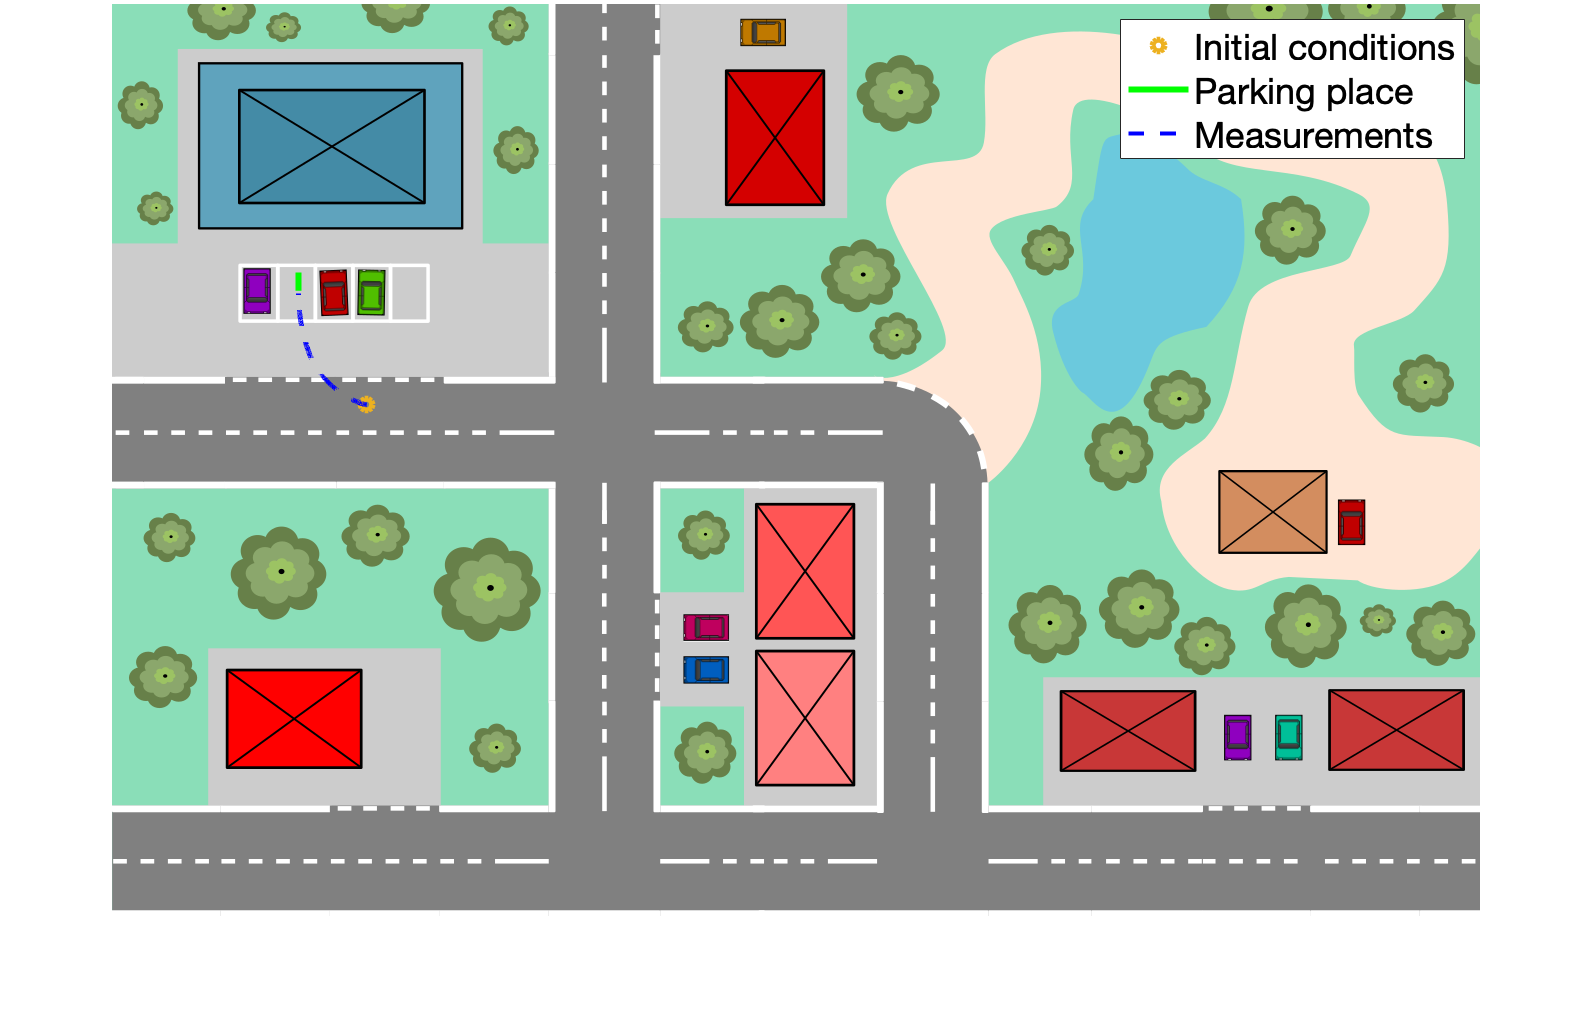

%
% Unicycle
%

% Initial conditions
unicycle.ic.theta = pi;
unicycle.ic.x = 2.8;
unicycle.ic.y = 5.6;

%
% Tracking reference signal
%
% Set initial conditions 
park.x0 = unicycle.ic.x;
park.y0 = unicycle.ic.y;
park.theta0 = unicycle.ic.theta;

% Tracking reference signal (empty)
tracking.time = [0];
tracking.v_ts = timeseries([park.x0], tracking.time);
tracking.w_ts = timeseries([park.y0], tracking.time);

%
% Obstacle
%
obstacle.p = [0; 0];

%
% Parking place
%
park.x = 2.05;
park.y = 6.85;
park.theta = pi/2;
park.t = 0.2 * [cos(park.theta); sin(park.theta)];

%
% Simulation
%
simulation.starting_controller = 2;
simulation.stop_time = 10;
set_param('simulation_scheme_vel/Reference generator/Tracking/NonHolonomic/Integrator1','InitialCondition','park.theta0');
set_param('simulation_scheme_vel/Reference generator/Tracking/NonHolonomic/Integrator2','InitialCondition','[park.x0 park.y0]');
set_param('simulation_scheme_vel/Reference generator/Tracking/final_p_ref','Value','[unicycle.ic.x; unicycle.ic.y]');
set_param('simulation_scheme_vel/Reference generator/Tracking/final_theta_ref','Value','unicycle.ic.theta');
out = sim('simulation_scheme_vel.slx');

%
% Results
%
figure(5);
imshow(map.img.data); % image
hold on;
plot(x_view(unicycle.ic.x, map.x_max, map.img.width), ...
    y_view(unicycle.ic.y, map.y_max, map.img.height), ...
    'o', 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250]); % Initial conditions
plot(x_view([park.x, park.x + park.t(1)], map.x_max, map.img.width), ...
    y_view([park.y, park.y + park.t(2)], map.y_max, map.img.height), ...
    '-', 'LineWidth', 3, 'Color', 'green'); % Parking place
plot(x_view(out.p.Data(:,1), map.x_max, map.img.width), ...
    y_view(out.p.Data(:,2), map.y_max, map.img.height), ...
    'LineWidth', 2, 'LineStyle', '--', 'Color', 'blue'); % Measurements
lgd = legend('Initial conditions', 'Parking place', 'Measurements');
lgd.FontSize = 18;

## Unicycle state

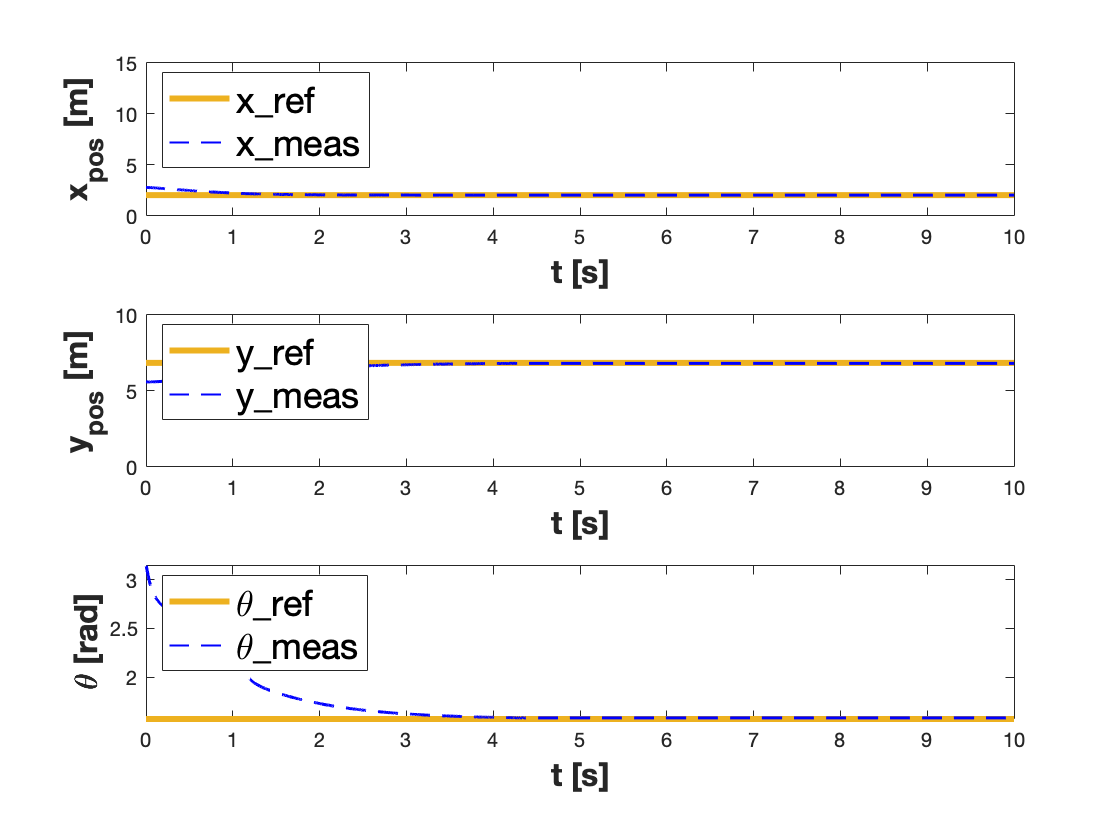

figure(6);
subplot(3,1,1);
plot(out.p_ref.Time, out.p_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.p.Time, out.p.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("x_{pos} [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["x\_ref" "x\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
axis([0 simulation.stop_time  0 map.x_max])
hold off

subplot(3,1,2);
plot(out.p_ref.Time, out.p_ref.Data(:,2), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.p.Time, out.p.Data(:,2),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("y_{pos} [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["y\_ref" "y\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
axis([0 simulation.stop_time  0 map.y_max])
hold off

subplot(3,1,3);
plot(out.theta_ref.Time, out.theta_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.theta.Time, out.theta.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\theta [rad]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\theta\_ref" "\theta\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
hold off

## State errors

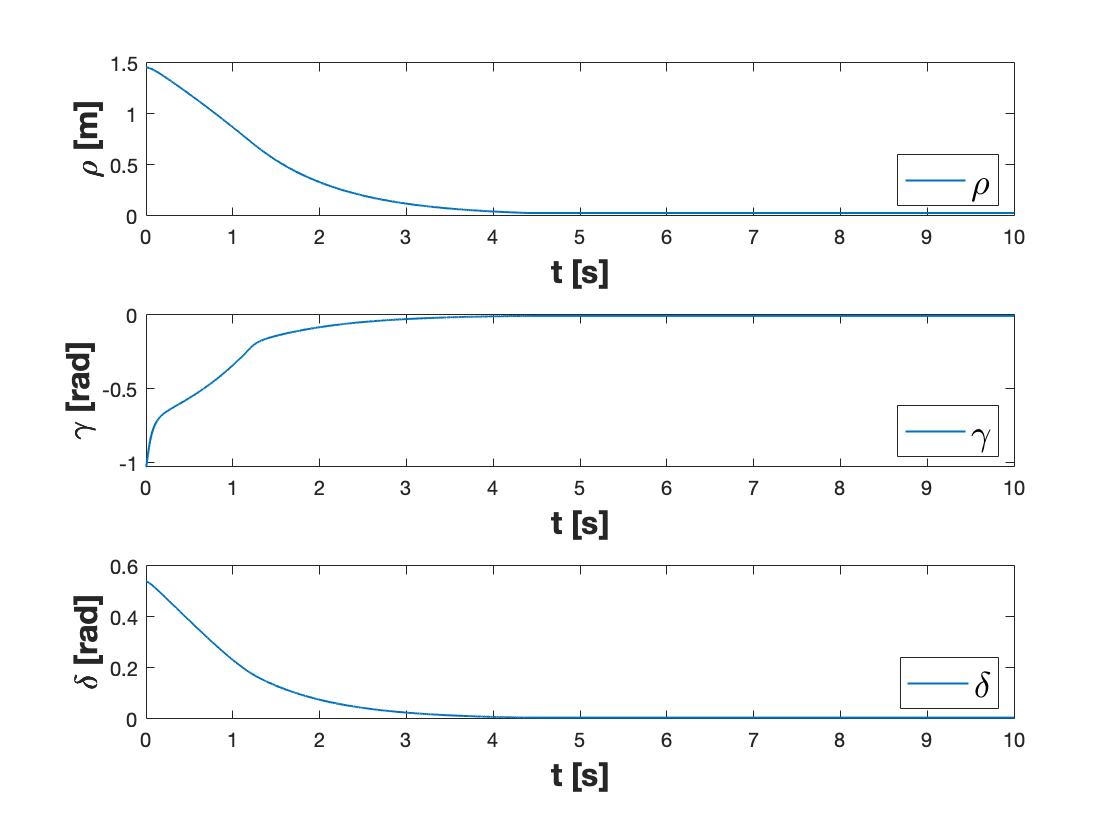

figure(7);
subplot(3,1,1);
plot(out.rho.Time, out.rho.Data(:,1), 'LineWidth', 1)
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\rho [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\rho"], 'Location', 'southeast');
lgd.FontSize = 18;
hold off

subplot(3,1,2);
plot(out.gamma.Time, out.gamma.Data(:,1), 'LineWidth', 1)
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\gamma [rad]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\gamma"], 'Location', 'southeast');
lgd.FontSize = 18;
hold off

subplot(3,1,3);
plot(out.delta.Time, out.delta.Data(:,1), 'LineWidth', 1)
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\delta [rad]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\delta"], 'Location', 'southeast');
lgd.FontSize = 18;
hold off

## Control effort

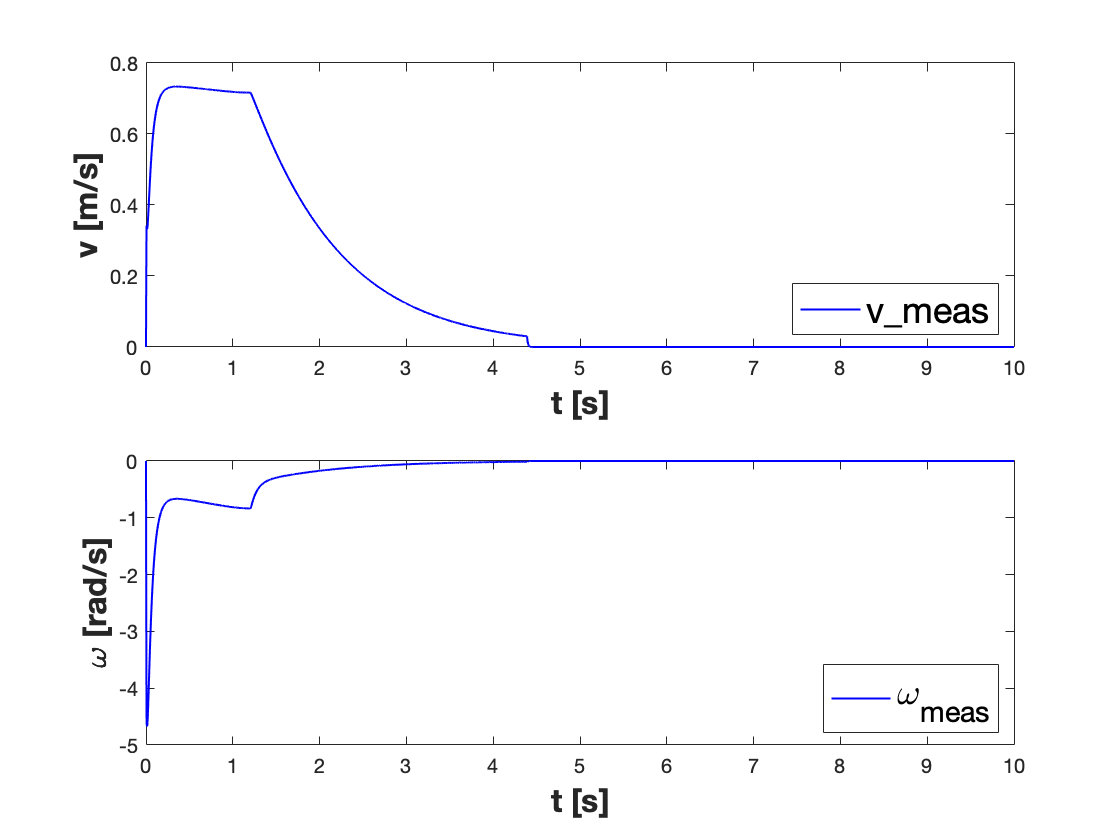

figure(8);
subplot(2,1,1)
plot(out.v.Time, out.v.Data(:,1),'LineWidth', 1, 'LineStyle', '-', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("v [m/s]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["v\_meas"], 'Location', 'southeast');
lgd.FontSize = 18;
hold off

subplot(2,1,2)
plot(out.w.Time, out.w.Data(:,1),'LineWidth', 1, 'LineStyle', '-', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\omega [rad/s]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\omega_{meas}"], 'Location', 'southeast');
lgd.FontSize = 18;
hold off

# Tracking + obstacle avoidance (straight stretch) --> Reference expressed in v,w

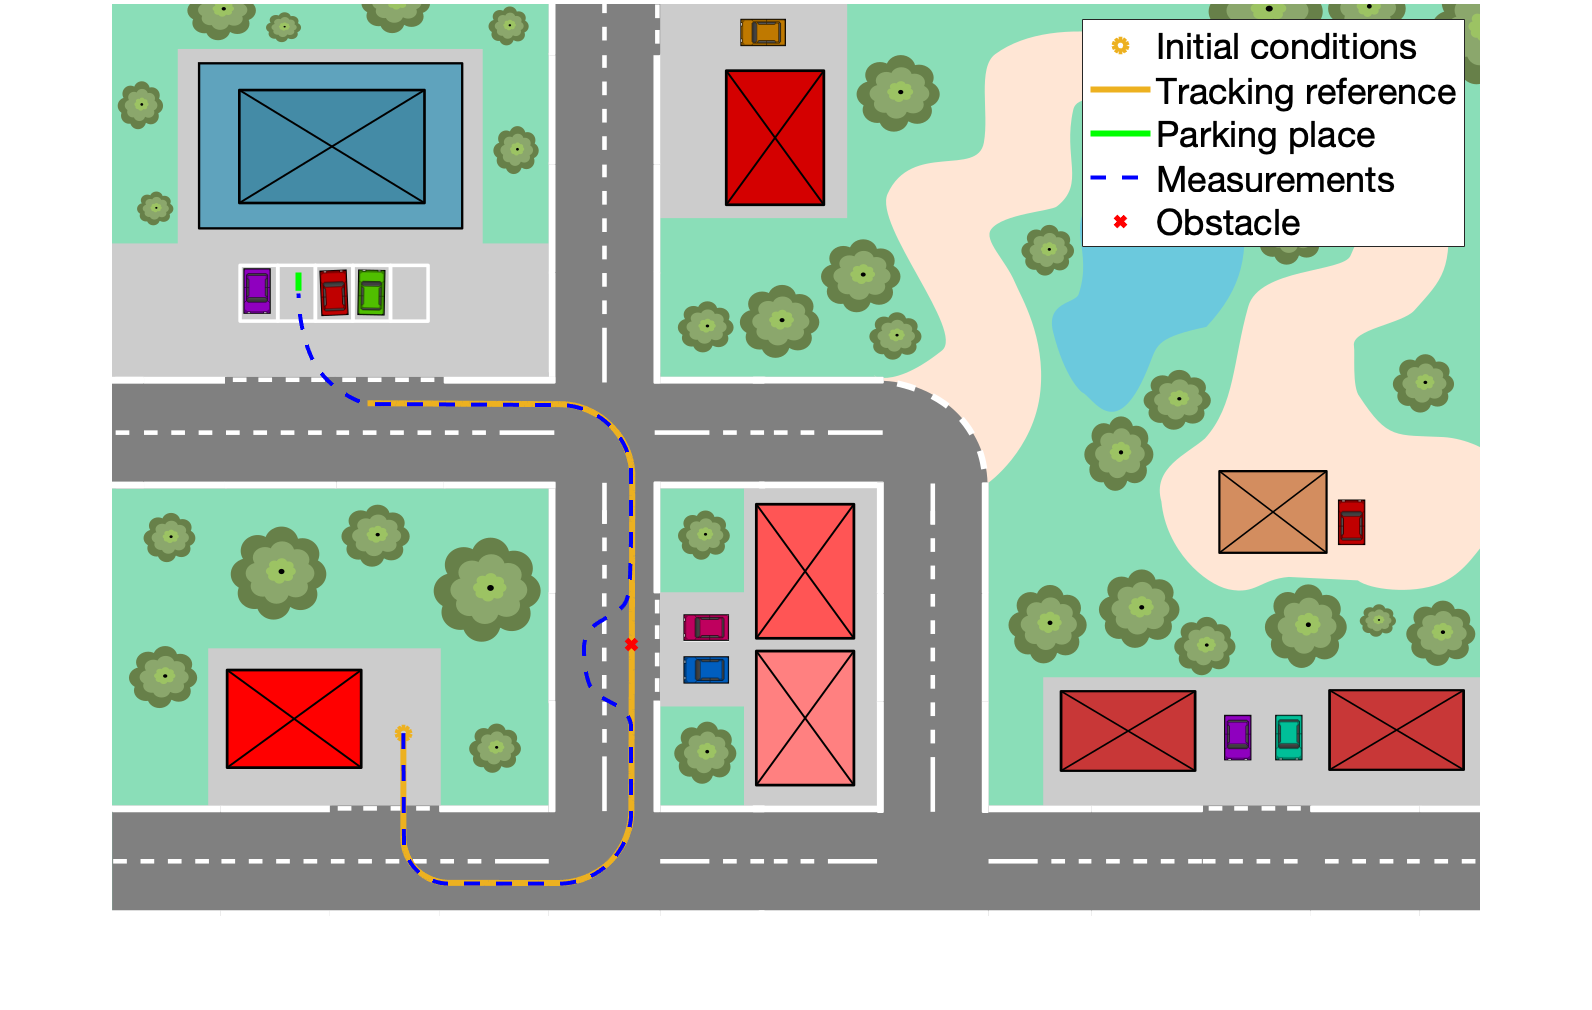

%
% Unicycle
%
% Initial conditions
unicycle.ic.theta = -pi/2;
unicycle.ic.x = 3.2;
unicycle.ic.y = 2.;

%
% Tracking reference signal
%
% Set initial conditions
tracking.x0 = unicycle.ic.x;
tracking.y0 = unicycle.ic.y;
tracking.theta0 = unicycle.ic.theta;

% Steering points
tracking.points = [tracking.x0, tracking.y0; 3.2, 0.85; 3.70, 0.35; 4.9, 0.35; 
               5.7, 1.15; 5.7, 4.8; 4.9, 5.6; 2.8, 5.6];

% Kind of reference --> 0: horizontal/vertical/curvilinear stretches
%                   --> 1: smooth lines
% Compute the reference signals for the first subpath: v, w
tracking.kind_reference = 0;
[tracking.x, tracking.y, tracking.theta, tracking.v, tracking.w] = generate_reference(tracking.points(:,1), tracking.points(:,2), ...
                                tracking.x0, tracking.y0, tracking.theta0, unicycle.diffDrive.Td, tracking.kind_reference);

% Define reference signals as timeseries
tracking.time = 0 : unicycle.diffDrive.Td : (length(tracking.v) - 1) * unicycle.diffDrive.Td;
tracking.v_ts = timeseries(tracking.v, tracking.time);
tracking.w_ts = timeseries(tracking.w, tracking.time);

%
% Obstacle
%
obstacle.p = [5.7; 2.975];

%
% Parking place
%
park.x = 2.05;
park.y = 6.85;
park.theta = pi/2;
park.t = 0.2 * [cos(park.theta); sin(park.theta)];

%
% Simulation
%
simulation.starting_controller = 1;
simulation.stop_time = 30;
set_param('simulation_scheme_vel/Reference generator/Tracking/NonHolonomic/Integrator1','InitialCondition','tracking.theta0');
set_param('simulation_scheme_vel/Reference generator/Tracking/NonHolonomic/Integrator2','InitialCondition','[tracking.x0 tracking.y0]');
set_param('simulation_scheme_vel/Reference generator/Tracking/final_p_ref','Value','tracking.points(end,:)');
set_param('simulation_scheme_vel/Reference generator/Tracking/final_theta_ref','Value','tracking.theta(end)');
out = sim('simulation_scheme_vel.slx');

%
% Results
%
figure(9);
imshow(map.img.data); % image
hold on;
plot(x_view(unicycle.ic.x, map.x_max, map.img.width), ...
    y_view(unicycle.ic.y, map.y_max, map.img.height), ...
    'o', 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250]); % Initial conditions
plot(x_view(tracking.x, map.x_max, map.img.width), ...
    y_view(tracking.y, map.y_max, map.img.height), ...
    'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250]); % Tracking reference signal
plot(x_view([park.x, park.x + park.t(1)], map.x_max, map.img.width), ...
    y_view([park.y, park.y + park.t(2)], map.y_max, map.img.height), ...
    '-', 'LineWidth', 3, 'Color', 'green'); % Parking place
plot(x_view(out.p.Data(:,1), map.x_max, map.img.width), ...
    y_view(out.p.Data(:,2), map.y_max, map.img.height), ...
    'LineWidth', 2, 'LineStyle', '--', 'Color', 'blue'); % Measurements
plot(x_view(obstacle.p(1), map.x_max, map.img.width), ...
    y_view(obstacle.p(2), map.y_max, map.img.height), ...
    'x', 'LineWidth', 3, 'Color', 'red'); % Obstacle
lgd = legend('Initial conditions', 'Tracking reference', 'Parking place', 'Measurements', 'Obstacle');
lgd.FontSize = 18;

## Unicycle state

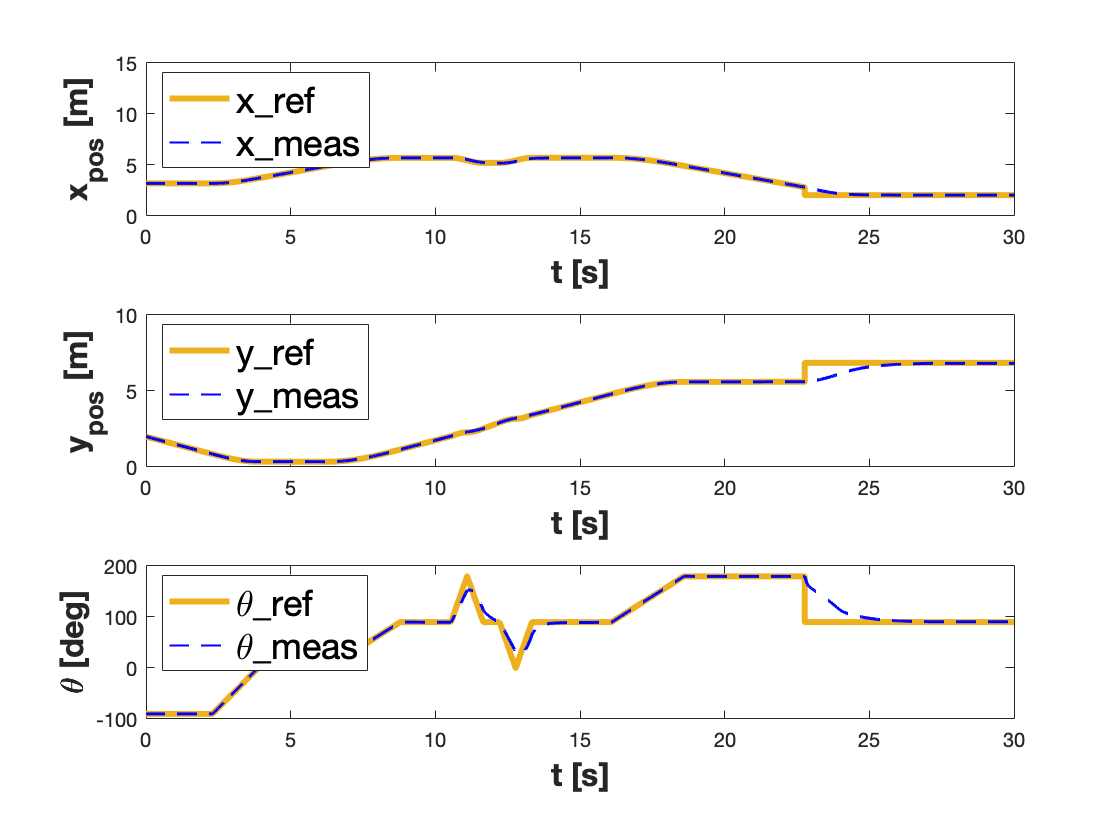

figure(10);
subplot(3,1,1);
plot(out.p_ref.Time, out.p_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.p.Time, out.p.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("x_{pos} [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["x\_ref" "x\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
axis([0 simulation.stop_time  0 map.x_max])
hold off

subplot(3,1,2);
plot(out.p_ref.Time, out.p_ref.Data(:,2), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.p.Time, out.p.Data(:,2),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("y_{pos} [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["y\_ref" "y\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
axis([0 simulation.stop_time  0 map.y_max])
hold off

subplot(3,1,3);
plot(out.theta_ref.Time, out.theta_ref.Data(:,1) .* rad2deg, 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.theta.Time, out.theta.Data(:,1).* rad2deg,'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\theta [deg]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\theta\_ref" "\theta\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
hold off

## Control effort

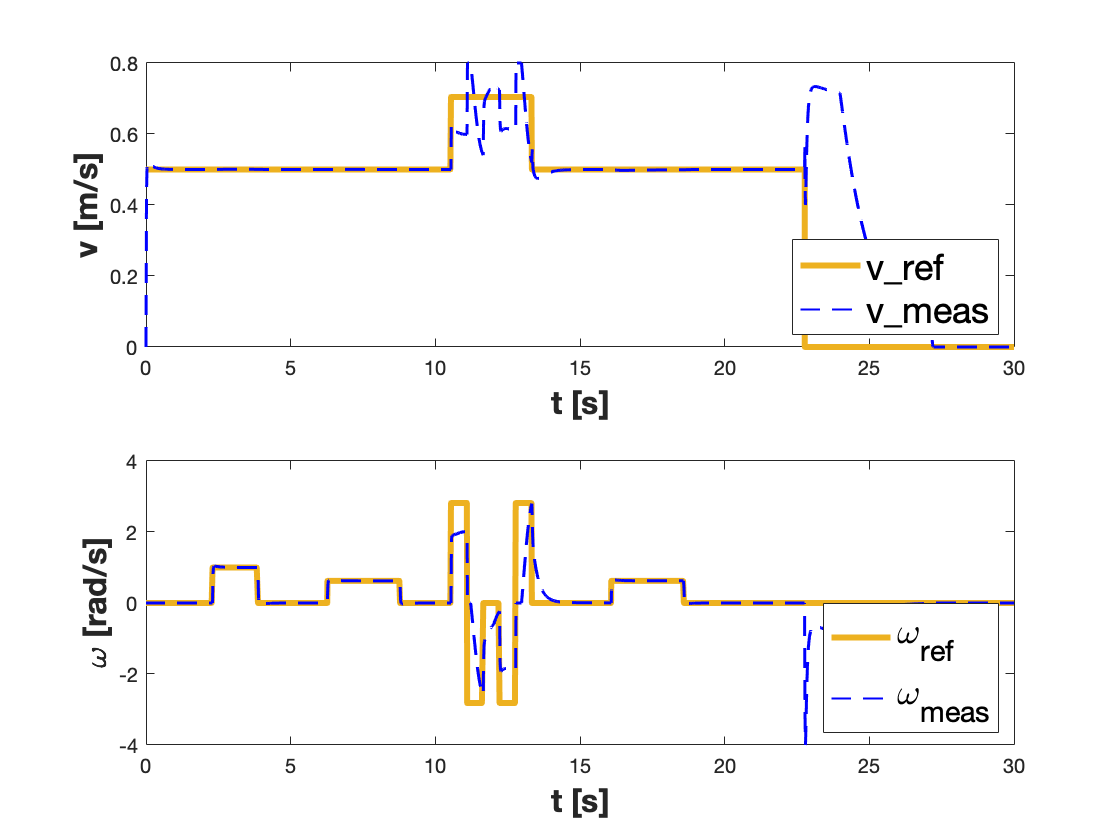

figure(11);
subplot(2,1,1)
plot(out.v_ref.Time, out.v_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.v.Time, out.v.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("v [m/s]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["v\_ref" "v\_meas"], 'Location', 'southeast');
lgd.FontSize = 18;
hold off

subplot(2,1,2)
plot(out.w_ref.Time, out.w_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.w.Time, out.w.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\omega [rad/s]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\omega_{ref}" "\omega_{meas}"], 'Location', 'southeast');
lgd.FontSize = 18;
hold off

# Tracking + obstacle avoidance (curvilinear stretch) --> Reference expressed in v,w

# FAILURE

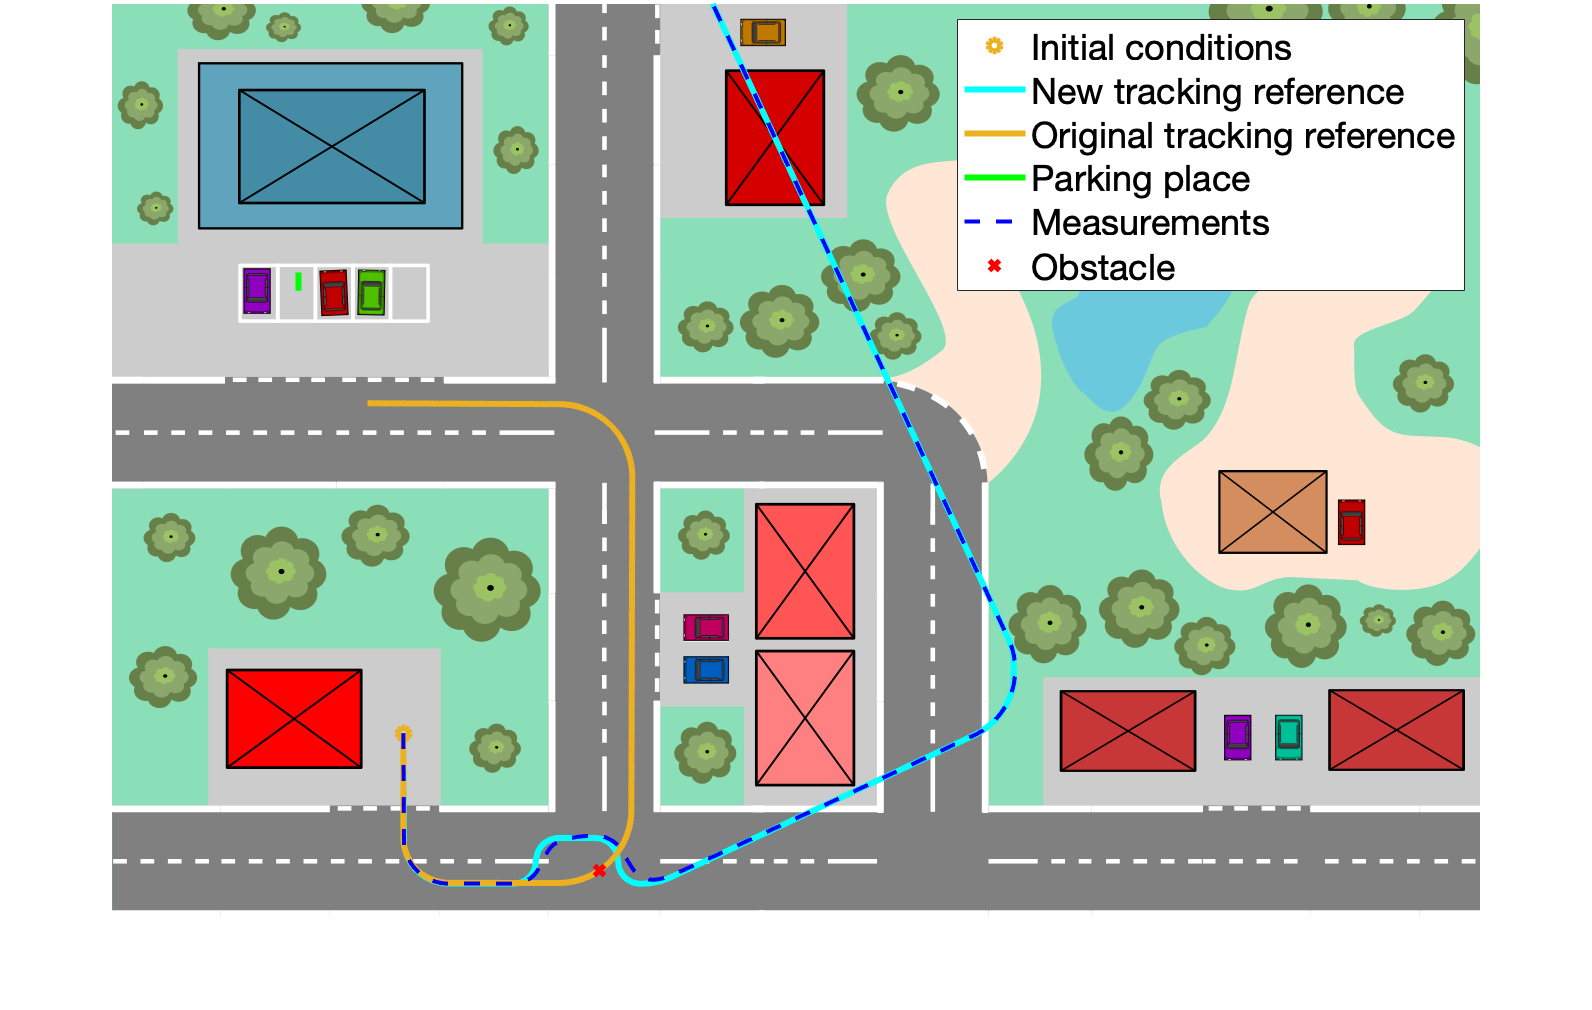

%
% Unicycle
%
% Initial conditions
unicycle.ic.theta = -pi/2;
unicycle.ic.x = 3.2;
unicycle.ic.y = 2.;

%
% Tracking reference signal
%
% Set initial conditions
tracking.x0 = unicycle.ic.x;
tracking.y0 = unicycle.ic.y;
tracking.theta0 = unicycle.ic.theta;

% Steering points
tracking.points = [tracking.x0, tracking.y0; 3.2, 0.85; 3.70, 0.35; 4.9, 0.35; 
               5.7, 1.15; 5.7, 4.8; 4.9, 5.6; 2.8, 5.6];

% Kind of reference --> 0: horizontal/vertical/curvilinear stretches
%                   --> 1: smooth lines
% Compute the reference signals for the first subpath: v, w
tracking.kind_reference = 0;
[tracking.x, tracking.y, tracking.theta, tracking.v, tracking.w] = generate_reference(tracking.points(:,1), tracking.points(:,2), ...
                                tracking.x0, tracking.y0, tracking.theta0, unicycle.diffDrive.Td, tracking.kind_reference);

% Define reference signals as timeseries
tracking.time = 0 : unicycle.diffDrive.Td : (length(tracking.v) - 1) * unicycle.diffDrive.Td;
tracking.v_ts = timeseries(tracking.v, tracking.time);
tracking.w_ts = timeseries(tracking.w, tracking.time);

%
% Obstacle
%
obstacle.p = [tracking.x(723); tracking.y(723)];

%
% Parking place
%
park.x = 2.05;
park.y = 6.85;
park.theta = pi/2;
park.t = 0.2 * [cos(park.theta); sin(park.theta)];

%
% Simulation
%
simulation.starting_controller = 1;
simulation.stop_time = 40;
set_param('simulation_scheme_vel/Reference generator/Tracking/NonHolonomic/Integrator1','InitialCondition','tracking.theta0');
set_param('simulation_scheme_vel/Reference generator/Tracking/NonHolonomic/Integrator2','InitialCondition','[tracking.x0 tracking.y0]');
set_param('simulation_scheme_vel/Reference generator/Tracking/final_p_ref','Value','tracking.points(end,:)');
set_param('simulation_scheme_vel/Reference generator/Tracking/final_theta_ref','Value','tracking.theta(end)');
out = sim('simulation_scheme_vel.slx');

%
% Results
%
figure(12);
imshow(map.img.data); % image
hold on;
plot(x_view(unicycle.ic.x, map.x_max, map.img.width), ...
    y_view(unicycle.ic.y, map.y_max, map.img.height), ...
    'o', 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250]); % Initial conditions
plot(x_view(out.p_ref.Data(:,1), map.x_max, map.img.width), ...
    y_view(out.p_ref.Data(:,2), map.y_max, map.img.height), ...
    'LineWidth', 3, 'Color', 'cyan'); % New reference signal
plot(x_view(tracking.x, map.x_max, map.img.width), ...
    y_view(tracking.y, map.y_max, map.img.height), ...
    'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250]); % Tracking reference signal
plot(x_view([park.x, park.x + park.t(1)], map.x_max, map.img.width), ...
    y_view([park.y, park.y + park.t(2)], map.y_max, map.img.height), ...
    '-', 'LineWidth', 3, 'Color', 'green'); % Parking place
plot(x_view(out.p.Data(:,1), map.x_max, map.img.width), ...
    y_view(out.p.Data(:,2), map.y_max, map.img.height), ...
    'LineWidth', 2, 'LineStyle', '--', 'Color', 'blue'); % Measurements
plot(x_view(obstacle.p(1), map.x_max, map.img.width), ...
    y_view(obstacle.p(2), map.y_max, map.img.height), ...
    'x', 'LineWidth', 3, 'Color', 'red'); % Obstacle
lgd = legend('Initial conditions', 'New tracking reference', 'Original tracking reference', 'Parking place', 'Measurements', 'Obstacle');
lgd.FontSize = 18;

# Tracking + obstacles avoidance (curvilinear stretch + straight stretch) --> Reference expressed in x,y

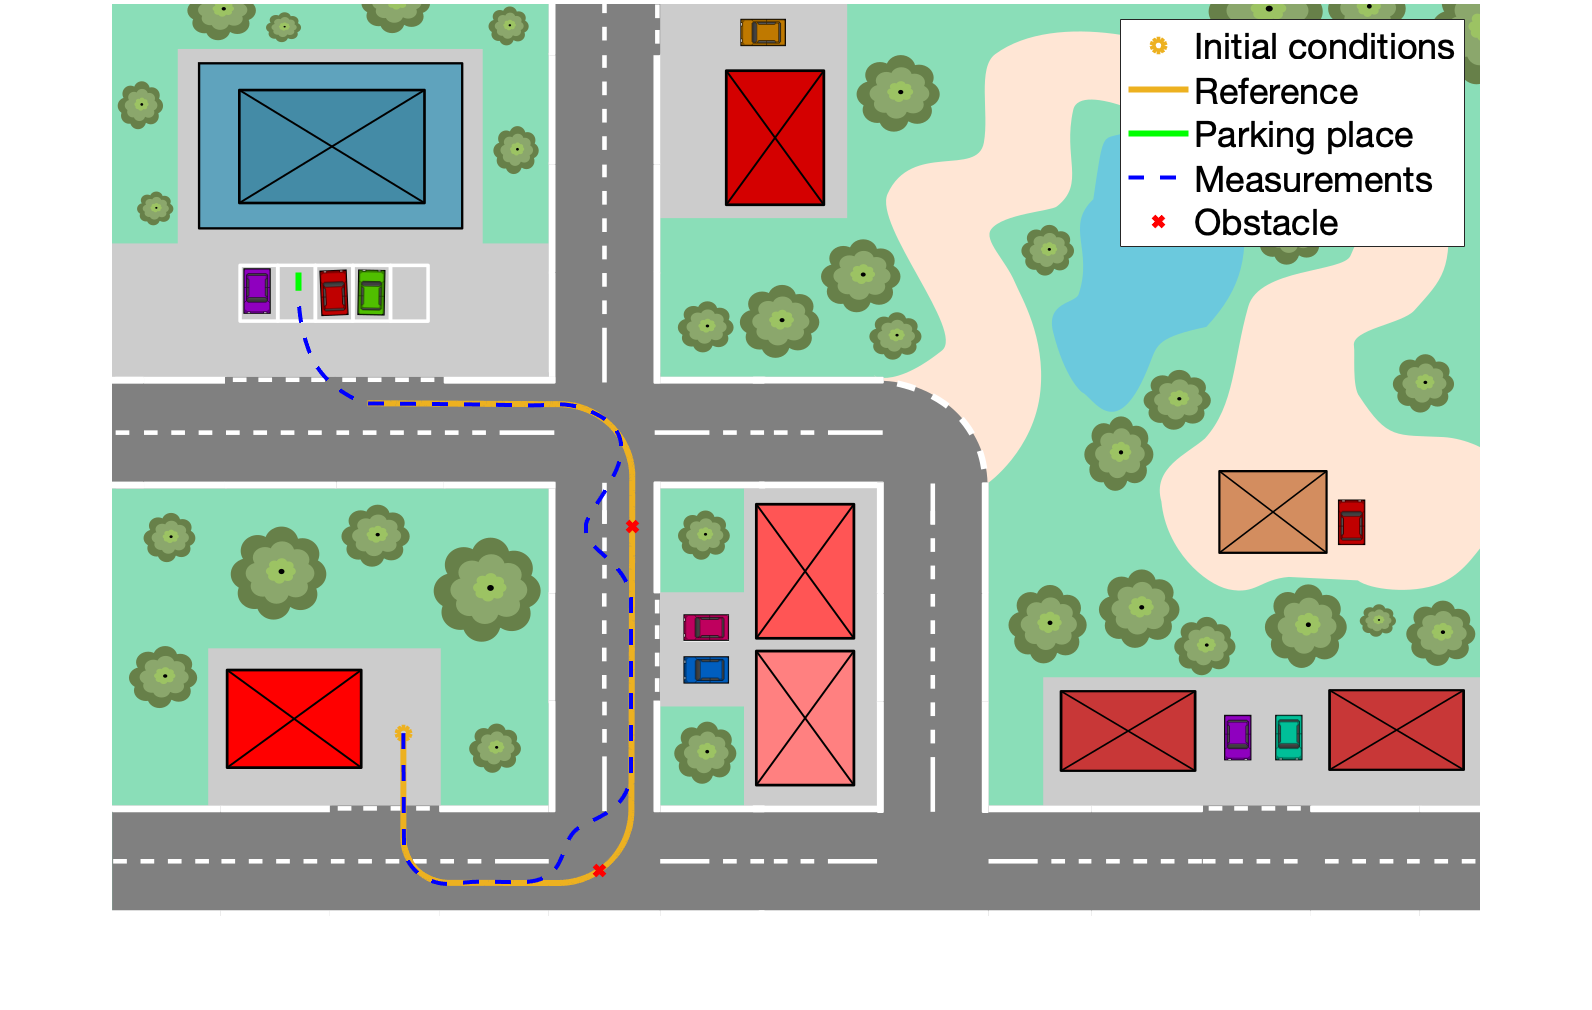

%
% Unicycle
%
% Initial conditions
unicycle.ic.theta = -pi/2;
unicycle.ic.x = 3.2;
unicycle.ic.y = 2.;

%
% Tracking reference signal
%
% Set initial conditions
tracking.x0 = unicycle.ic.x;
tracking.y0 = unicycle.ic.y;
tracking.theta0 = unicycle.ic.theta;

% Steering points
tracking.points = [tracking.x0, tracking.y0; 3.2, 0.85; 3.70, 0.35; 4.9, 0.35; 
               5.7, 1.15; 5.7, 4.8; 4.9, 5.6; 2.8, 5.6];

% Kind of reference --> 0: horizontal/vertical/curvilinear stretches
%                   --> 1: smooth lines
% Compute the reference signals for the first subpath: v, w
tracking.kind_reference = 0;
[tracking.x, tracking.y, tracking.theta, tracking.v, tracking.w] = generate_reference(tracking.points(:,1), tracking.points(:,2), ...
                                tracking.x0, tracking.y0, tracking.theta0, unicycle.diffDrive.Td, tracking.kind_reference);

% Define reference signals as timeseries
tracking.time = 0 : unicycle.diffDrive.Td : (length(tracking.v) - 1) * unicycle.diffDrive.Td;
tracking.v_ts = timeseries(tracking.v, tracking.time);
tracking.w_ts = timeseries(tracking.w, tracking.time);

%
% Obstacle
%
obstacle.p = [tracking.x(723) tracking.x(1500) ; tracking.y(723) tracking.y(1500)];

%
% Parking place
%
park.x = 2.05;
park.y = 6.85;
park.theta = pi/2;
park.t = 0.2 * [cos(park.theta); sin(park.theta)];

%
% Simulation
%
simulation.starting_controller = 1;
simulation.stop_time = 40;
tracking.distance_obstacle = 0.5; % How far to generate the overcoming manouver from the obstacle
tracking = rmfield(tracking,'v_ts'); % Remove field v_ts from tracking
tracking = rmfield(tracking,'w_ts'); % Remove field w_ts from tracking
set_param('simulation_scheme_pos/Reference generator/Tracking/final_p_ref','Value','tracking.points(end,:)');
set_param('simulation_scheme_pos/Reference generator/Tracking/final_theta_ref','Value','tracking.theta(end)');
out = sim('simulation_scheme_pos.slx');

%
% Results
%
figure(13);
imshow(map.img.data); % image
hold on;
plot(x_view(unicycle.ic.x, map.x_max, map.img.width), ...
    y_view(unicycle.ic.y, map.y_max, map.img.height), ...
    'o', 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250]); % Initial conditions
plot(x_view(tracking.x, map.x_max, map.img.width), ...
    y_view(tracking.y, map.y_max, map.img.height), ...
    'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250]); % Tracking reference signal
plot(x_view([park.x, park.x + park.t(1)], map.x_max, map.img.width), ...
    y_view([park.y, park.y + park.t(2)], map.y_max, map.img.height), ...
    '-', 'LineWidth', 3, 'Color', 'green'); % Parking place
plot(x_view(out.p.Data(:,1), map.x_max, map.img.width), ...
    y_view(out.p.Data(:,2), map.y_max, map.img.height), ...
    'LineWidth', 2, 'LineStyle', '--', 'Color', 'blue'); % Measurements
plot(x_view(obstacle.p(1,:), map.x_max, map.img.width), ...
    y_view(obstacle.p(2,:), map.y_max, map.img.height), ...
    'x', 'LineWidth', 3, 'Color', 'red'); % Obstacle
lgd = legend('Initial conditions', 'Reference', 'Parking place','Measurements', 'Obstacle');
lgd.FontSize = 18;

## Unicycle state

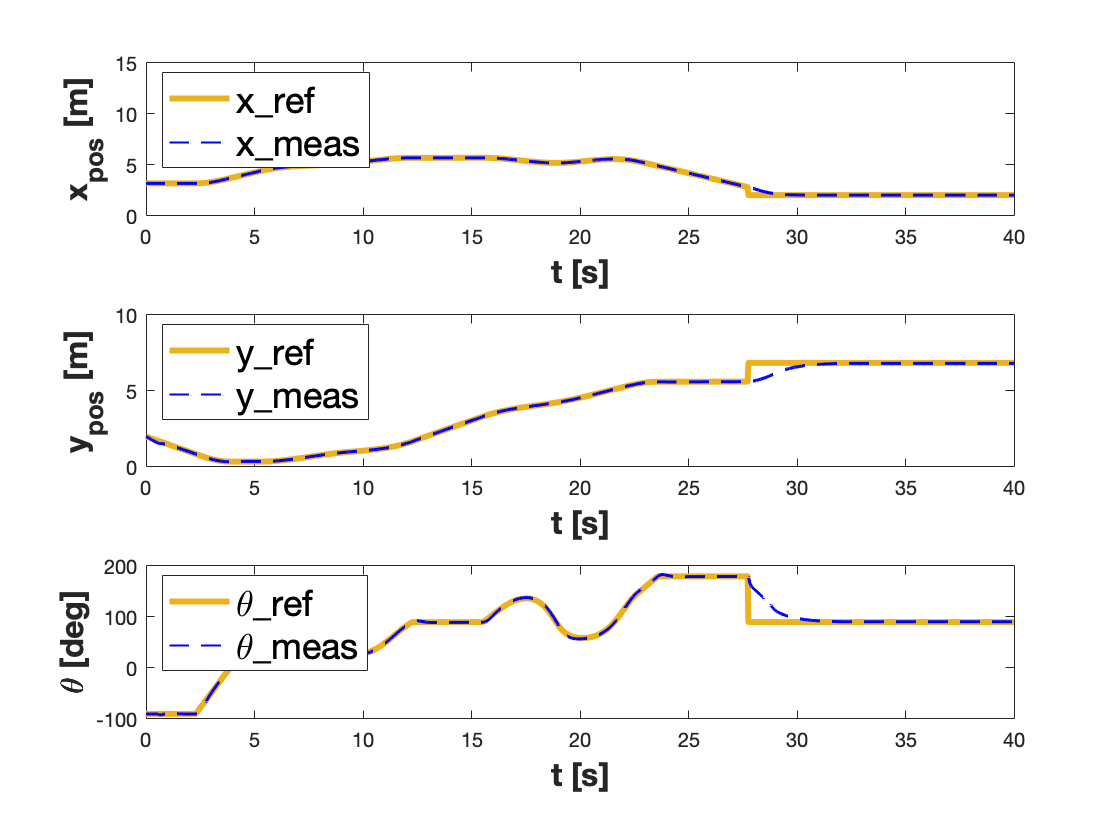

figure(14);
subplot(3,1,1);
plot(out.p_ref.Time, out.p_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.p.Time, out.p.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("x_{pos} [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["x\_ref" "x\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
axis([0 simulation.stop_time  0 map.x_max])
hold off

subplot(3,1,2);
plot(out.p_ref.Time, out.p_ref.Data(:,2), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.p.Time, out.p.Data(:,2),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("y_{pos} [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["y\_ref" "y\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
axis([0 simulation.stop_time  0 map.y_max])
hold off

subplot(3,1,3);
plot(out.theta_ref.Time, out.theta_ref.Data(:,1) .* rad2deg, 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.theta.Time, out.theta.Data(:,1).* rad2deg,'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\theta [deg]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\theta\_ref" "\theta\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
hold off

## Control effort

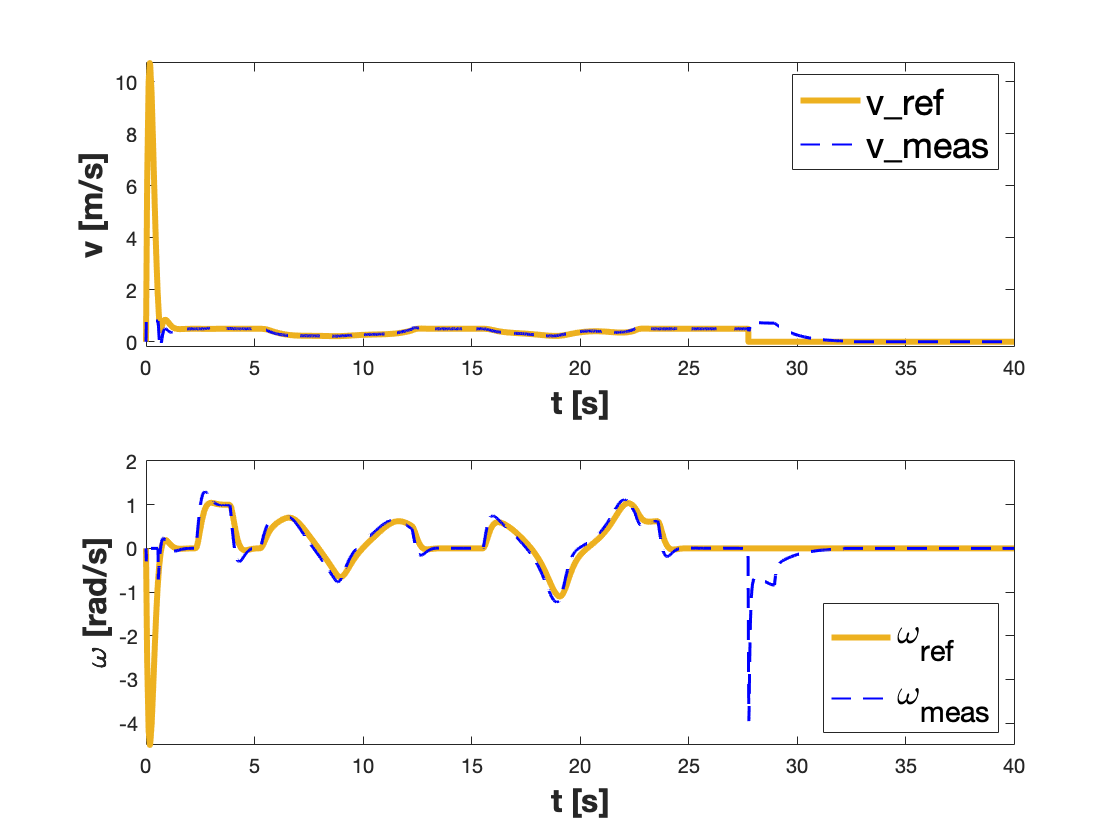

figure(15);
subplot(2,1,1)
plot(out.v_ref.Time, out.v_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.v.Time, out.v.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("v [m/s]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["v\_ref" "v\_meas"], 'Location', 'northeast');
lgd.FontSize = 18;
hold off

subplot(2,1,2)
plot(out.w_ref.Time, out.w_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.w.Time, out.w.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\omega [rad/s]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\omega_{ref}" "\omega_{meas}"], 'Location', 'southeast');
lgd.FontSize = 18;
hold off

# Final track 

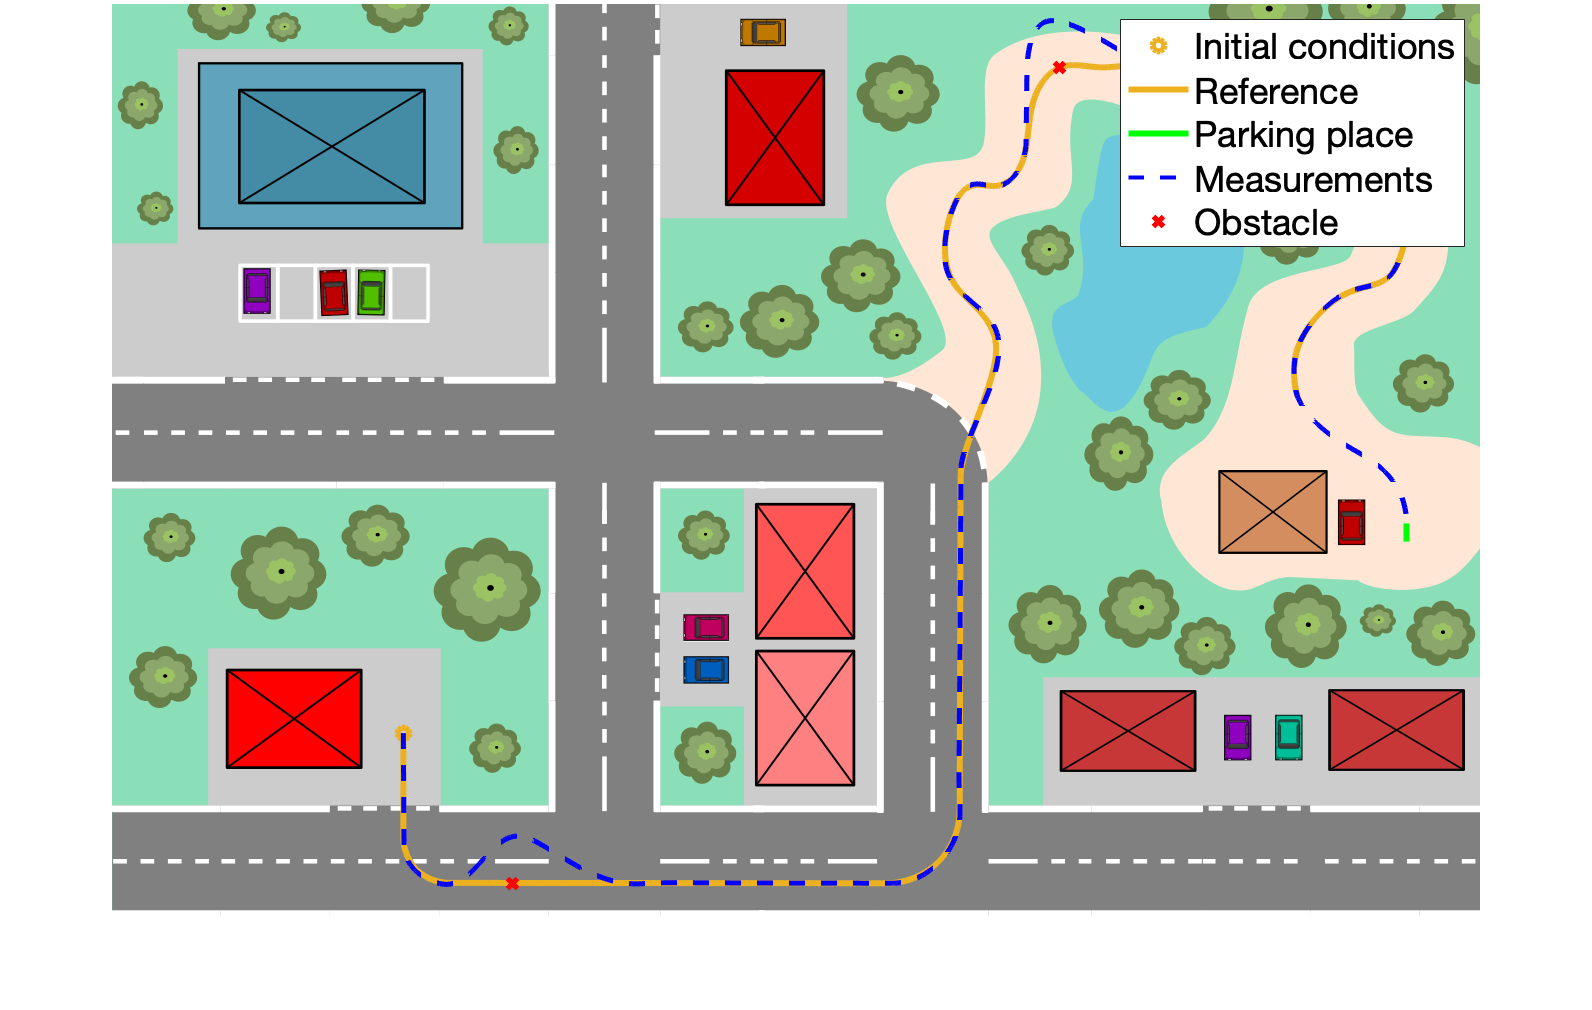

% Initial conditions
unicycle.ic.theta = -pi/2;
unicycle.ic.x = 3.2;
unicycle.ic.y = 2.;

%
% First subpath
%
% Set initial conditions
tracking.x0 = unicycle.ic.x;
tracking.y0 = unicycle.ic.y;
tracking.theta0 = unicycle.ic.theta;

% Steering points
% path.points = [path.x0, path.y0; 3.2, 0.85; 3.70, 0.35; 4.9, 0.35; 
%               5.7, 1.15; 5.7, 4.8; 4.9, 5.6; 2.8, 5.6];
tracking.points_kind0 = [tracking.x0, tracking.y0; 3.2, 0.85; 3.70, 0.35;
                 8.5, 0.35; 9.3, 1.15; 9.3, 4.8];
% path.points = [path.x0, path.y0; 3.2, 0.85; 3.70, 0.35;
%                8.5, 0.35; 9.3, 1.15; 9.3, 5.4; 9.5, 5.6; 9.9, 6; 9.8, 8]

% Kind of reference --> 0: horizontal/vertical/curvilinear stretches
%                   --> 1: smooth lines
% Compute the reference signals for the first subpath: x, y and theta
tracking.kind_reference = 0;
[tracking.x_kind0, tracking.y_kind0, tracking.theta_kind0, tracking.v_kind0, tracking.w_kind0] = generate_reference(tracking.points_kind0(:,1), tracking.points_kind0(:,2), ...
                                tracking.x0, tracking.y0, tracking.theta0, unicycle.diffDrive.Td, tracking.kind_reference,0,0);

% Define reference signals as timeseries
% path.time = 0:unicycle.diffDrive.Td:(length(path.v_kind0) - 1)*unicycle.diffDrive.Td;
% path.v_ts = timeseries(path.v_kind0, path.time);
% path.w_ts = timeseries(path.w_kind0, path.time);

%
% Second subpath
%
tracking.points_kind1 = [9.311, 4.811; 9.7, 6.2; 9.2, 7; 9.3, 7.9; 9.7, 8;
                     10, 8.3; 10.1, 8.9; 10.4, 9.3; 10.85, 9.3; 11.3, 9.3; 11.75, 9.05; 12.2, 8.8;
                     13.1, 8.5; 14, 8.2; 14.2, 7.8; 14.2, 7.5; 14, 7; 13.5, 6.8; 13, 6.2; 13, 5.7];

% Compute the reference signals for the second subpath: x, y and theta
tracking.kind_reference = 1;
[tracking.x_kind1, tracking.y_kind1, tracking.theta_kind1, v_kind1, w_kind1] = generate_reference(tracking.points_kind1(:,1), tracking.points_kind1(:,2), ...
                                tracking.x0, tracking.y0, tracking.theta0, unicycle.diffDrive.Td, tracking.kind_reference, 0, 1);

% Combining the 2 subpaths
tracking.x = cat(2, tracking.x_kind0, tracking.x_kind1);
tracking.y = cat(2, tracking.y_kind0, tracking.y_kind1);
tracking.theta = cat(2, tracking.theta_kind0, tracking.theta_kind1);
tracking.points = [tracking.points_kind0; tracking.points_kind1];

%
% Obstacle
%
% obstacle.p = [5.7 2.975];
obstacle.p = [4.4 10.4; 0.35 9.3];

%
% Parking place
%
park.x = 14.2;
park.y = 4.3;
park.theta = -pi/2;
park.t = 0.2 * [cos(park.theta); sin(park.theta)];

%
% Simulation
%
tracking.distance_obstacle = 0.5; % How far to generate the overcoming manouver from the obstacle
simulation.stop_time = 75;
set_param('simulation_scheme_pos/Reference generator/Tracking/final_p_ref','Value','tracking.points(end,:)');
set_param('simulation_scheme_pos/Reference generator/Tracking/final_theta_ref','Value','tracking.theta(end)');
out = sim('simulation_scheme_pos.slx');

%
% Results
%
figure(16);
imshow(map.img.data); % image
hold on;
plot(x_view(unicycle.ic.x, map.x_max, map.img.width), ...
    y_view(unicycle.ic.y, map.y_max, map.img.height), ...
    'o', 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250]); % Initial conditions
plot(x_view(tracking.x, map.x_max, map.img.width), ...
    y_view(tracking.y, map.y_max, map.img.height), ...
    'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250]); % Tracking reference signal
plot(x_view([park.x, park.x + park.t(1)], map.x_max, map.img.width), ...
    y_view([park.y, park.y + park.t(2)], map.y_max, map.img.height), ...
    '-', 'LineWidth', 3, 'Color', 'green'); % Parking place
plot(x_view(out.p.Data(:,1), map.x_max, map.img.width), ...
    y_view(out.p.Data(:,2), map.y_max, map.img.height), ...
    'LineWidth', 2, 'LineStyle', '--', 'Color', 'blue'); % Measurements
plot(x_view(obstacle.p(1,:), map.x_max, map.img.width), ...
    y_view(obstacle.p(2,:), map.y_max, map.img.height), ...
    'x', 'LineWidth', 3, 'Color', 'red'); % Obstacle

%plot(x_view(tracking.points_kind1(:,1), map.x_max, map.img.width), ...
%    y_view(tracking.points_kind1(:,2), map.y_max, map.img.height), ...
%    'o', 'LineWidth', 3, 'Color', 'red');
lgd = legend('Initial conditions', 'Reference', 'Parking place', 'Measurements', 'Obstacle');
lgd.FontSize = 18;

## Unicycle state

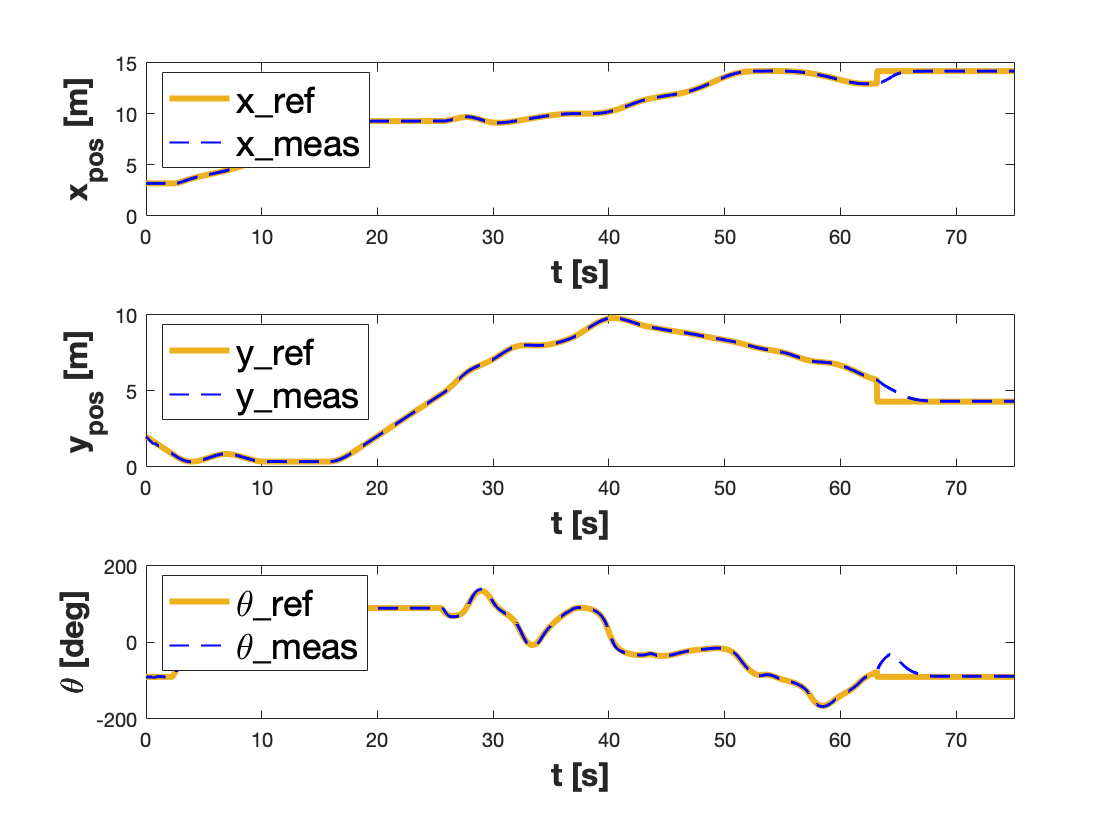

figure(17);
subplot(3,1,1);
plot(out.p_ref.Time, out.p_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.p.Time, out.p.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("x_{pos} [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["x\_ref" "x\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
axis([0 simulation.stop_time  0 map.x_max])
hold off

subplot(3,1,2);
plot(out.p_ref.Time, out.p_ref.Data(:,2), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.p.Time, out.p.Data(:,2),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("y_{pos} [m]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["y\_ref" "y\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
axis([0 simulation.stop_time  0 map.y_max])
hold off

subplot(3,1,3);
plot(out.theta_ref.Time, out.theta_ref.Data(:,1) .* rad2deg, 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.theta.Time, out.theta.Data(:,1).* rad2deg,'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\theta [deg]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\theta\_ref" "\theta\_meas"], 'Location', 'northwest');
lgd.FontSize = 18;
xlim([0 simulation.stop_time])
hold off

## Control effort

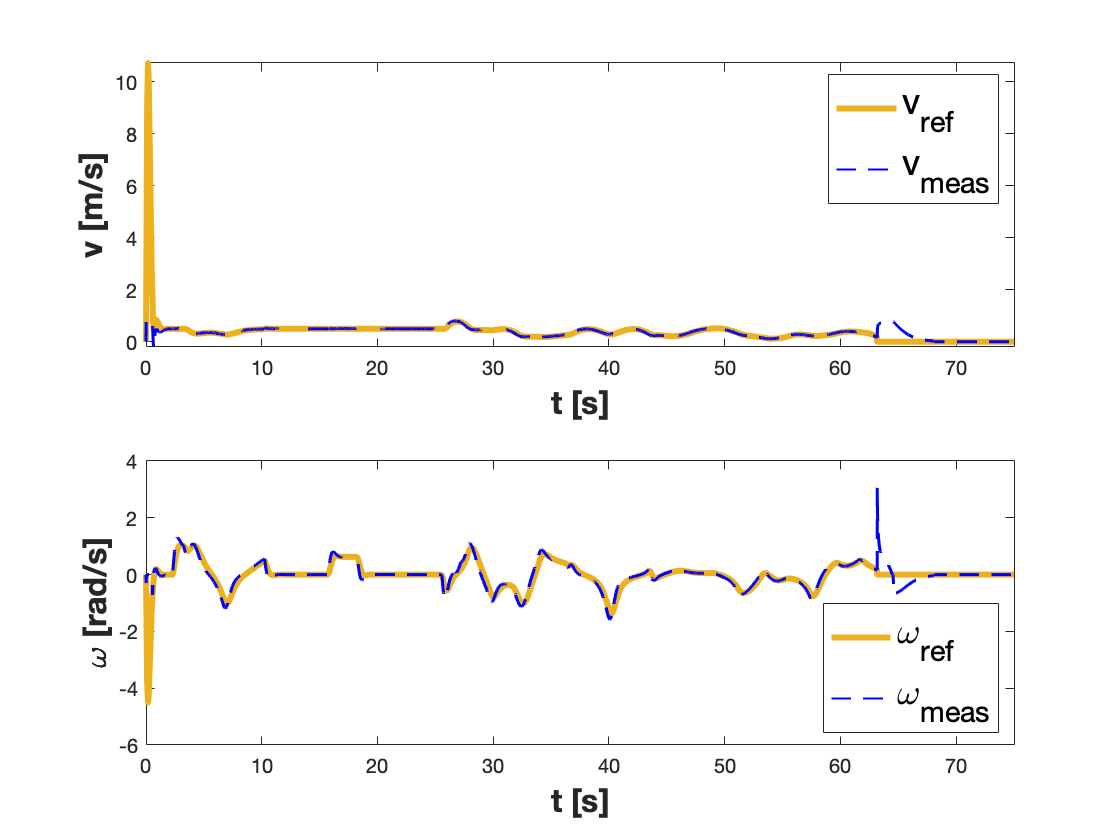

figure(18);
subplot(2,1,1)
plot(out.v_ref.Time, out.v_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.v.Time, out.v.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("v [m/s]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["v_{ref}" "v_{meas}"], 'Location', 'northeast');
lgd.FontSize = 18;
xlim([0 simulation.stop_time])
hold off

subplot(2,1,2)
plot(out.w_ref.Time, out.w_ref.Data(:,1), 'LineWidth', 3, 'Color', [0.9290 0.6940 0.1250])
hold on
plot(out.w.Time, out.w.Data(:,1),'LineWidth', 1, 'LineStyle', '--', 'Color', 'blue')
xlabel("t [s]",'FontWeight','bold', 'FontSize', 16')
ylabel("\omega [rad/s]",'FontWeight','bold', 'FontSize', 16')
lgd = legend(["\omega_{ref}" "\omega_{meas}"], 'Location', 'southeast');
lgd.FontSize = 18;
xlim([0 simulation.stop_time])
hold off